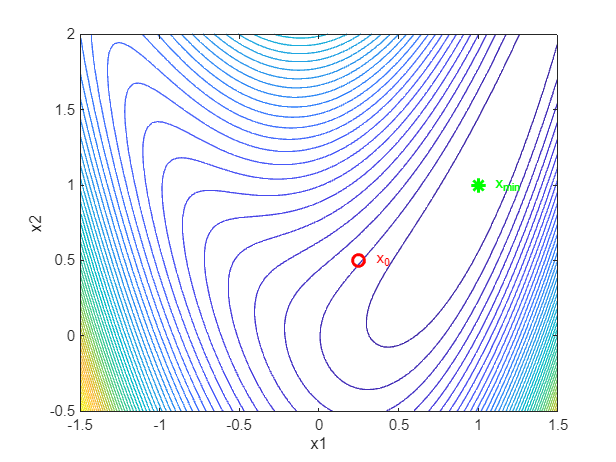

% Objective function
fun = @(x1, x2) 2.5*(x1.^2-x2).^2+(1-x1).^2;
f = @(x) fun(x(1), x(2));

% Parameters
eps = 1e-3;
Nmax = 100;

% Orthogonal basis for 2 variables
d = [1 0;0 1];

% Starting point
x0 = [0.25;0.5];
[x_min1, N1] = powell(x0, d, eps, Nmax, f);

% --- Contour plot ---
x1 = linspace(-1.5, 1.5, 100);
x2 = linspace(-0.5, 2, 100);
[X1, X2] = meshgrid(x1, x2);
Z = fun(X1, X2);

figure;
contour(X1, X2, Z, 50);
xlabel('x1');
ylabel('x2');;
hold on;

% Mark starting point
plot(x0(1), x0(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
text(x0(1), x0(2), '  x_0', 'Color','r');

% Mark minimum found by Powell's method
plot(x_min1(1), x_min1(2), 'g*', 'MarkerSize', 10, 'LineWidth', 2);
text(x_min1(1), x_min1(2), '  x_{min}', 'Color','g');